# 第一周任务一 配电网时序潮流计算

储能231 梁宏熙 学号206231315 城市23节点配电网，alpha=1.03，节点4、9、14各接0.8MW光伏，无储能。 各时段从基准算例重新构造有功、无功负荷，并扣除光伏有功注入。 $P_{i,t}^{net}=\alpha P_{i,0}^{load}\lambda_t^{load}-P_{i,t}^{pv}$ 全天网损由24小时交流有功损耗乘以1小时步长后累加得到。

clear;clc;close all;
work_dir=fileparts(mfilename('fullpath'));addpath(work_dir);
case_dir=week1_environment(work_dir);
Student=struct('Name','梁宏熙','Pinyin','lianghongxi','Class','储能231','ID',206231315);
Stu_ID=Student.ID;

## 计算基态及负荷增加百分之十的灵敏度

最大、最小电压均从全节点、全时段矩阵提取；记录薄弱节点及时段。 核心潮流循环、图形及独立记录位于配套week1_task12.m中。

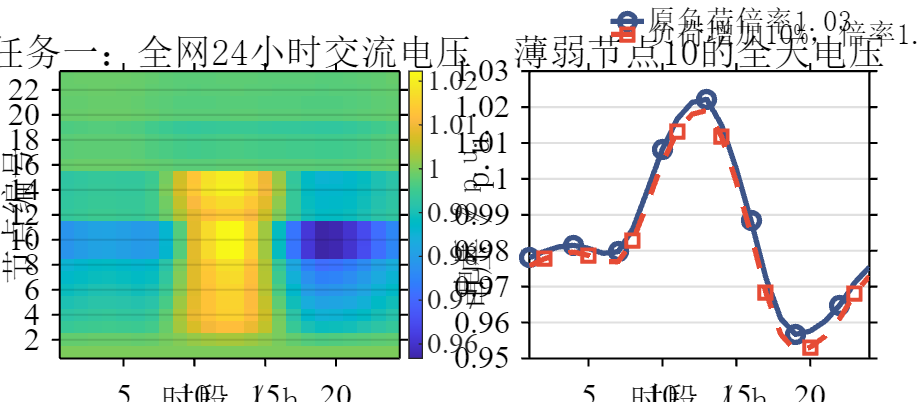

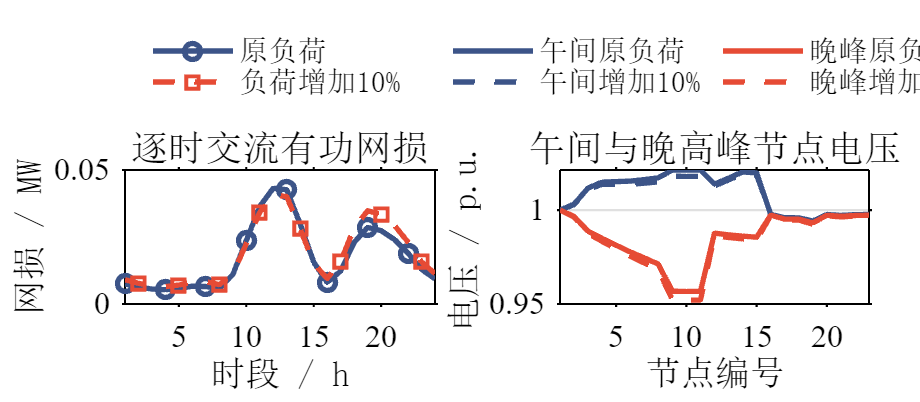

    LoadMultiplier    Alpha    PVPerBus_MW    MinVoltage_pu    MinVoltageNode    MinVoltageHour    MaxVoltage_pu    DailyLoss_MWh    NoonMinVoltage_pu    EveningMinVoltage_pu    NoonLoss_MW    EveningLoss_MW    ConvergedHours
    ______________    _____    ___________    _____________    ______________    ______________    _____________    _____________    _________________    ____________________    ___________    ______________    ______________

           1           1.03        0.8           0.95671             10                19             1.0223            0.4165             0.9942               0.95671            0.043224          0.02856             24      
         1.1          1.133        0.8           0.95211             10                19             1.0194           0.45405            0.99362               0.95211            0.040649         0.034797             24      



Task1=week1_task12(work_dir,Student,case_dir,1);

## 结果与思考题

负荷上升会提高支路电流并加大线路压降，晚高峰电压通常进一步下降。 午间同时受到光伏注入影响，网损变化须以实际潮流结果为准。

disp(struct2table(Task1.Task1));

    LoadMultiplier    Alpha    PVPerBus_MW    MinVoltage_pu    MinVoltageNode    MinVoltageHour    MaxVoltage_pu    DailyLoss_MWh    NoonMinVoltage_pu    EveningMinVoltage_pu    NoonLoss_MW    EveningLoss_MW    ConvergedHours
    ______________    _____    ___________    _____________    ______________    ______________    _____________    _____________    _________________    ____________________    ___________    ______________    ______________

           1           1.03        0.8           0.95671             10                19             1.0223            0.4165             0.9942               0.95671            0.043224          0.02856             24      
         1.1          1.133        0.8           0.95211             10                19             1.0194           0.45405            0.99362               0.95211            0.040649         0.034797             24      



fprintf('任务一完成，比较原负荷alpha=1.03与增加10%%后的alpha=1.133。\n');

任务一完成，比较原负荷alpha=1.03与增加10%后的alpha=1.133。
